## **CARNOTŮV CYKLUS**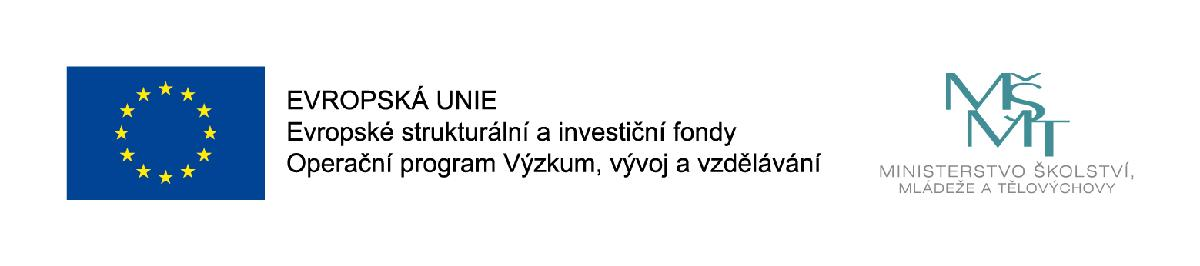

#### prof. Ing. Josef STETINA, Ph.D. / Vysoké učení technické v Brně

#### email: josef.stetina@vutbr.cz

#### www: http://termomechanika.online/

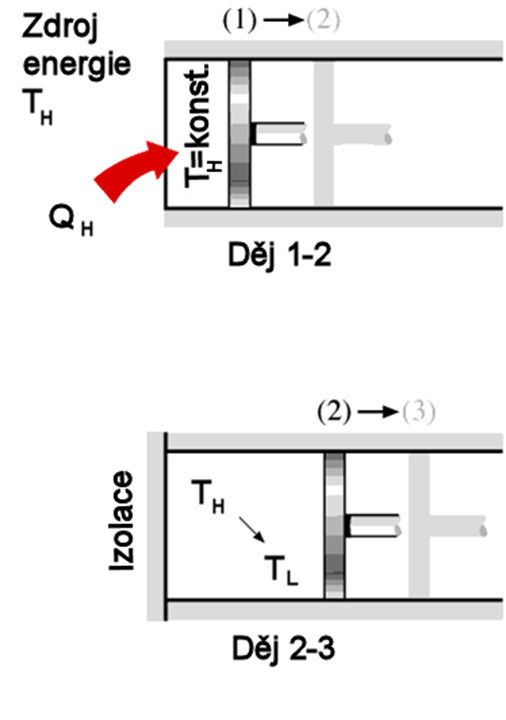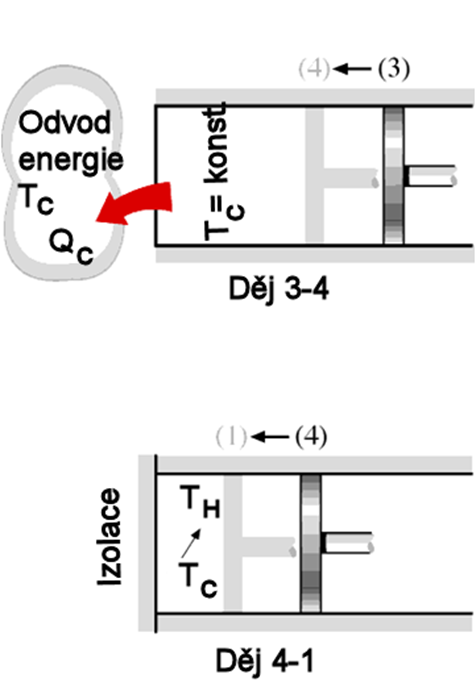

Cyklus se dá uskutečnit různými způsoby. Buď se jednotlivé změny provádějí v různých strojích, nebo v jediném válci tepelného stroje.

Sadí Carnot si položil otázku (ve své práci „Réflexions sur la puissance motrice du feu", 1824), jakým způsobem může pístový tepelný stroj periodicky pracující mezi dvěma tepelnými zásobníky (např. ohřívákem a chladičem) získat maximální práci z tepla přivedeného v pracovní látce. Navrhl cyklus tzv. *Carnotův**vratný cyklus *který se skládá ze dvou expanzních změn, izotermy a adiabaty, a ze dvou změn kompresních, rovněž izotermy a adiabaty.

Podmínky vratnosti Carnotova cyklu jsou: 

a) Pracovní látka musí být ve stálé termické i mechanické rovnováze s okolím.

b) Výměna tepla ze zásobníku musí probíhat při konstantních teplotách zásobníku.

c) V průběhu cyklu nesmí docházet k žádným ztrátám tepelným nebo mechanickým. (Píst i válce musí být dokonale tepelně izolovány a píst se musí pohybovat bez tření.)

Tyto podmínky nelze splnit a v praxi se jim můžeme pouze přiblížit. Carnotův cyklus má však praktický význam jako kritérium pro porovnání skutečných cyklů.

Vratný Carnotův cyklus probíhá takto: při izotermické expanzi *1 - 2 *je válec ve styku se teplým zásobníkem *I, *z níž přijímá teplo *q**H* při stálé teplotě *T**H**. *Při adiabatické expanzi *2 - 3 *je válec ve styku s tepelně izolovanou částí *III. *K provedení izotermické komprese *2 - 4 *se válec posune k lázni *II, *jíž předá teplo *q**C* při stálé teplotě lázně *T**C**. *Cyklus se uzavře adiabatickou kompresí *4-1, *při níž je dno válce opět tepelně izolováno částí *III. *

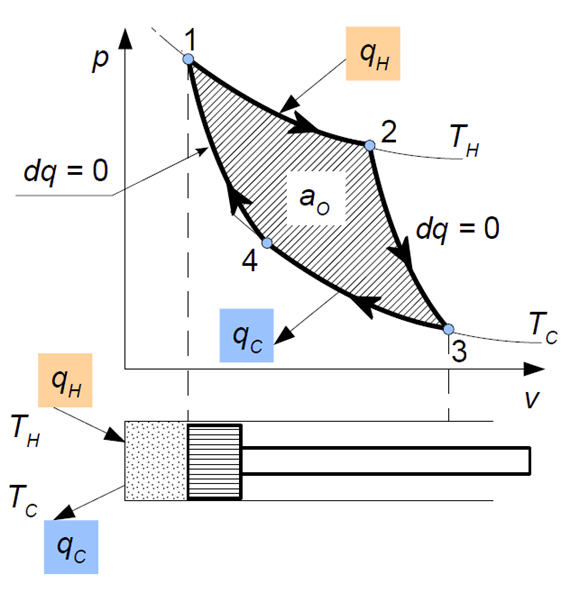

**Carnotův****cyklus slouží k porovnávání účinnosti jiných cyklů**

**Carnotův****cyklus přímý:**

***T******H*****, *****T******C ***  **zásobníky tepla**

**1 - 2**  **izotermická expanze (pomalá)**

**2 - 3**  **adiabatická expanze (rychlá)**

**3 - 4**  **izotermická komprese (pomalá)**

**4 - 1**  **adiabatická komprese (rychlá)**

**Předávané teplo - viz izotermický děj**


$$$q = {({c_v} \cdot dT + p \cdot dv)_T} = p \cdot dv = da$$$



$$${q_H} = {a_{12}} = \int\limits_1^2 {p\,dv}  = \int\limits_1^2 {r{T_H}\frac{{dv}}{v}}  = r{T_H}ln\frac{{{v_2}}}{{{v_1}}}$$$


**Příklad**

1,25 kilogramu vzduchu konß Carnot¨v obýh mezi teplotami 900 ░C a 199 ░C. NejvyÜÜÝ tlak je 4,5 MPa a nejni×ÜÝ 0,1 MPa. UrŔet stavovÚ veliŔiny v typickřch bodech obýhu., p°ivedenÚ teplo a odvedenÚho tepla, prßci obýhu % a termickou ˙Ŕinnost.

clear all;
m = 1.25;     % [kg]
t1 = 900;     % [°C]
t3 = 199;     % [°C]
p1MPa = 4.5;  % [MPa]
p3MPa = 0.1;  % [MPa]
%% Základní výpočty
rair  = 287.1;
kappa = 1.41;
cpair =kappa/(kappa-1)*rair;
cvair = 1/(kappa-1)*rair;
T1 = C2K(t1);
T3 = C2K(t3);
p1 = MPa2Pa(p1MPa);
p3 = MPa2Pa(p3MPa);
V1 = m*rair*T1/p1;
V3 = m*rair*T3/p3;
p2 = p3*(T1/T3)^(kappa/(kappa-1));
p4 = p1/(T1/T3)^(kappa/(kappa-1));
T2=T1;
T4=T3;
V2 = m*rair*T2/p2;
V4 = m*rair*T4/p4;
QH = m*rair*T1*log(p1/p2);
QC = m*rair*T3*log(p3/p4);
A0 = QH - abs(QC);
etat = 1 - T3/T1;
x = ['p_1 =' num2str(Pa2MPa(p1),6) ' MPa p_2 =' num2str(Pa2MPa(p2),6) ' MPa'];
disp(x);

p_1 =4.5 MPa p_2 =2.28747 MPa


x = ['p_3 =' num2str(Pa2MPa(p3),6) ' MPa p_4 =' num2str(Pa2MPa(p4),6) ' MPa' ];
disp(x);

p_3 =0.1 MPa p_4 =0.196724 MPa




x = ['Přivedené teplo =' num2str(QH/1000,6) ' kJ.' ];
disp(x);

P°ivedenÚ teplo =284.871 kJ.


x = ['Odvedené teplo =' num2str(QC/1000,6) ' kJ.' ];
disp(x);

OdvedenÚ teplo =-114.65 kJ.


x = ['Práce cyklu =' num2str(A0/1000,6) ' kJ.' ];
disp(x);

Prßce cyklu =170.221 kJ.


x = ['Termická úinnost carnotova cyklu =' num2str(etat,6) ' .' ];
disp(x);

Termickß ˙Ŕinnost carnotova cyklu =0.597537 .


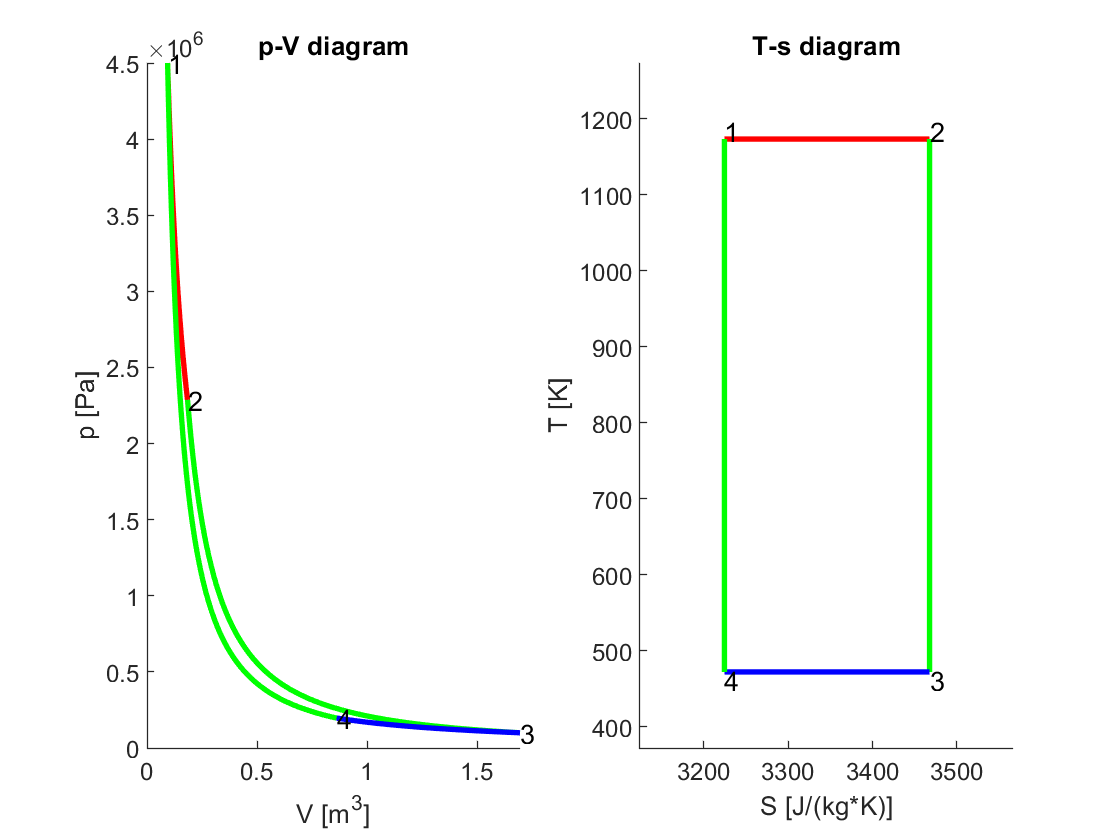

%% VřpoŔet izotermickÚho dýje
Vv12 = linspace(V1,V2,180);
pv12 = zeros([1,180]);
Tv12 = zeros([1,180]);
Sv12 = zeros([1,180]);
for i=2:180
  pv12(i) = p1*V1/Vv12(i);
  Tv12(i) = T1;
  Sv12(i)=m*cpair*log(Tv12(i))-m*rair*log(pv12(i));
end
pv12(1) = p1;
pv12(180) = p2;
Vv12(1) = V1;
Vv12(180) = V2;
Tv12(1) = T1;
Sv12(1)=m*cpair*log(Tv12(1))-m*rair*log(pv12(1));
%
Vv23 = linspace(V2,V3,180);
pv23 = zeros([1,180]);
Tv23 = zeros([1,180]);
Sv23 = zeros([1,180]);
for i=2:180
  pv23(i) = p2*V2^kappa/Vv23(i)^kappa;
  Tv23(i) = pv23(i) * Vv23(i) / (rair * m);
  Sv23(i)=m*cpair*log(Tv23(i))-m*rair*log(pv23(i));
end
pv23(1) = p2;
pv23(180) = p3;
Vv23(1) = V2;
Vv23(180) = V3;
Tv23(1) = pv23(1) * Vv23(1) / (rair * m);
Sv23(1)=m*cpair*log(Tv23(1))-m*rair*log(pv23(1));
%% VřpoŔet adiabatickÚho dýje
Vv34 = linspace(V3,V4,180);
pv34 = zeros([1,180]);
Tv34 = zeros([1,180]);
Sv34 = zeros([1,180]);
for i=2:180
  pv34(i) = p3*V3/Vv34(i);
  Tv34(i) = T3;
  Sv34(i)=m*cpair*log(Tv34(i))-m*rair*log(pv34(i));
end
pv34(1) = p3;
pv34(180) = p4;
Vv34(1) = V3;
Vv34(180) = V4;
Tv34(1) = T3;
Sv34(1)=m*cpair*log(Tv34(1))-m*rair*log(pv34(1));
%
Vv41 = linspace(V4,V1,180);
pv41 = zeros([1,180]);
Tv41 = zeros([1,180]);
Sv41 = zeros([1,180]);
for i=2:180
  pv41(i) = p4*V4^kappa/Vv41(i)^kappa;
  Tv41(i) = pv41(i) * Vv41(i) / (rair * m);
  Sv41(i)=m*cpair*log(Tv41(i))-m*rair*log(pv41(i));
end
pv41(1) = p4;
pv41(180) = p1;
Vv41(1) = V4;
Vv41(180) = V1;
Tv41(1) = pv41(1) * Vv41(1) / (rair * m);
Sv41(1)=m*cpair*log(Tv41(1))-m*rair*log(pv41(1));

%% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vv12,pv12,'r-','linewidth',2);
plot(Vv23,pv23,'g-','linewidth',2);
plot(Vv34,pv34,'b-','linewidth',2);
plot(Vv41,pv41,'g-','linewidth',2);
hold off;
% popis bod¨ diagramu
axis([0 V3 0 p1]);
text(Vv12(1),pv12(1)-0.2,'1');
text(Vv12(180),pv12(180)-0.2,'2');
text(Vv34(1),pv34(1)-0.2,'3');
text(Vv34(180),pv34(180)-0.2,'4');
% nßzev grafu a popisy os
title('p-V diagram')
xlabel('V [m^3]')
ylabel('p [Pa]')                     
subplot(1,2,2);
hold on;
plot(Sv12,Tv12,'r-','linewidth',2);
plot(Sv23,Tv23,'g-','linewidth',2);
plot(Sv34,Tv34,'b-','linewidth',2);
plot(Sv41,Tv41,'g-','linewidth',2);
hold off;
% popis bodů diagramu
axis([Sv12(1)-100 Sv34(1)+100 T3-100 T1+100]);
text(Sv12(1),Tv12(1)+10,'1');
text(Sv12(180),Tv12(180)+10,'2');
text(Sv34(1),Tv34(1)-10,'3');
text(Sv34(180),Tv34(180)-10,'4');
% nazev grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]')                      % ^\circC

### Lokální funkce 

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Pascalů

function [Pa] = MPa2Pa(MPa)
Pa = MPa*1000000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end